im27 = imread("IMAGE023.jpg");

curr_img = im27;
%curr_img = rgb2hsv(im27)
%curr_img = curr_img(:, :, 3)
imshow(curr_img)


small_gauss = imgaussfilt(5);
large_gauss = imgaussfilt(8);
%larger_gauss = imgaussfilt(11);

curr_img_gray = im2gray(curr_img);

small_blur = conv2(curr_img_gray, small_gauss);
%imshow(uint8(small_blur))
large_blur = conv2(curr_img_gray, large_gauss);
%imshow(uint8(large_blur))

img_diff = abs(small_blur - large_blur);

imshow(uint8(img_diff))


img_diff_one = (1/max(img_diff, [], "all")).*img_diff;

imshow(img_diff_one)

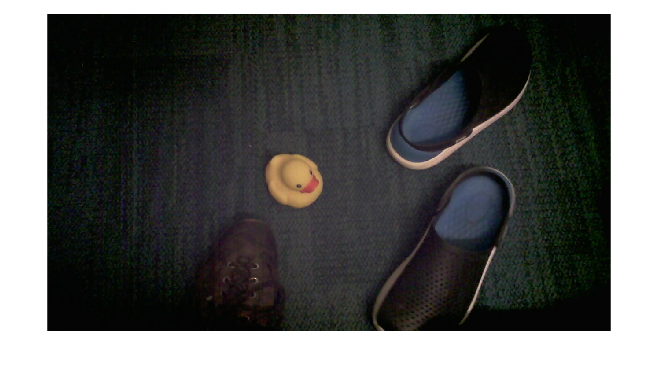


duck_filt = img_diff_one > 0.5;

img_diff_one(~duck_filt) = 0;
img_diff_one(duck_filt) = 1;

imshow(img_diff_one);

labels = bwlabel(img_diff_one);

best_blob = mode(labels(labels ~= 0), 'all')

best_blob = 2


labels(labels ~= best_blob) = 0

labels =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

labels(labels == best_blob) = 1

labels =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

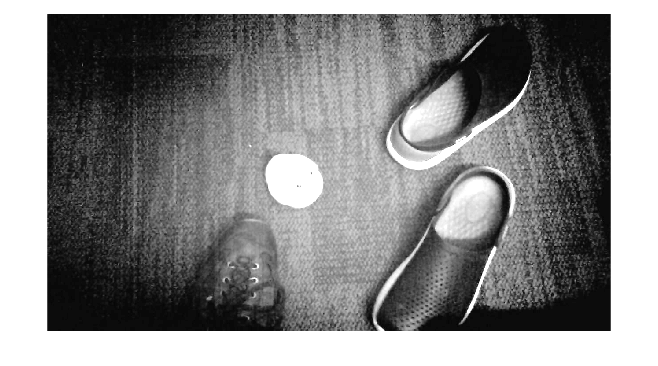


%[bstartrow, bstartcol] = ind2sub(size(labels), find(labels, 1, 'first'))
%[bendrow, bendcol] = ind2sub(size(labels), find(labels, 1, 'last'))
%bbox = [bstartrow, bstartcol, bendrow, bendcol]

duck_labels = labeloverlay(curr_img, labels);
%duck_box = insertShape(curr_img, "rectangle", bbox, "LineWidth",8)
imshow(duck_labels)


%duck_over = labeloverlay(uint8(img_diff), duck_filt);
%imshow(duck_over);